# MPC project

## model

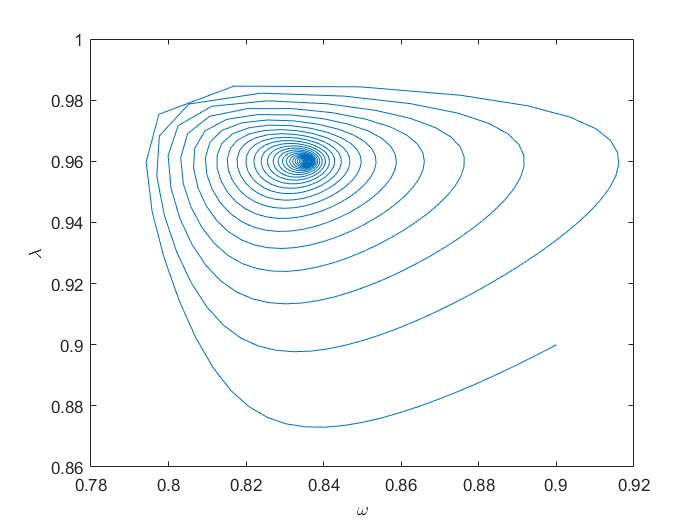

system = @Keen;
x0 = [0.9,0.9,0.1];
tspan = 1:0.1:100;
options = odeset('RelTol', 1E-7);


[t,x] = ode45(@(t,x) system(x),tspan,x0, options);

plot(x(:,1), x(:,2))
xlabel("\omega");
ylabel("\lambda")

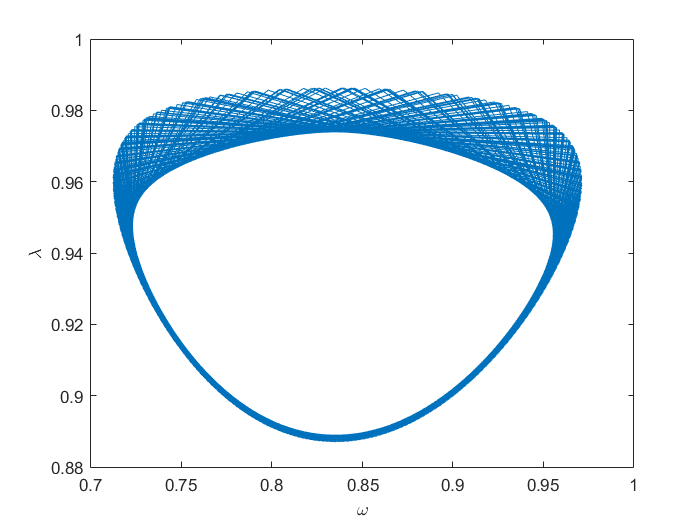

system = @Goodwin;
x0 = [0.9,0.9];
tspan = 1:1:1000;
options = odeset('RelTol', 1E-7);

[t,x] = ode45(@(t,x) system(x),tspan,x0,options);

plot(x(:,1), x(:,2))
xlabel("\omega");
ylabel("\lambda")

k(0.16)

ans = 0.1650

dk(0.16)

ans = 4.9999

phi(0.96)

ans = 0.0250

function y = Goodwin(x)
    % parameters
    alpha = 0.025;
    beta = 0.02;
    delta = 0.01;
    v = 3;
    y = zeros(2,1);
    omega = x(1); lambda = x(2);
    d_omega = omega * (phi(lambda) - alpha);
    d_lambda = lambda*((1-omega)/v - alpha- beta - delta);
    y(1) = d_omega; y(2) = d_lambda;
end

function y = Keen(x)
    % parameters
    alpha = 0.025;
    beta = 0.02;
    delta = 0.01;
    v = 3;
    r = 0.03;
    y = zeros(3,1);
    omega = x(1); lambda = x(2); debt = x(3);
    d_omega = omega * (phi(lambda) - alpha);
    d_lambda = lambda*(k(1-omega-r*debt)/v - alpha- beta - delta);
    d_debt = debt*(r - k(1-omega-r*debt)/v + delta) + k(1-omega-r*debt) - (1-omega);
    y(1) = d_omega; y(2) = d_lambda; y(3) = d_debt;
end

function y = phi(x)
    % the parameter should satisfy phi(0)=-0.04 phi(0.96)=0.025
    % from "Financial Instability Hypothesis"
    p1 = 1.0417e-04;
    p0 = 0.0401;
    y = p1 / (1-x)^2 - p0;
end

function y = k(x)
    % 
    k0 = 0.5;
    k1 = 1/pi;
    k2 = 63.9842; % 10.5
    k3 = -11.9906;% -4
    y = k0 + k1*atan(k2*x+k3);
end

function y = dk(x)
    k1 = 1/pi;
    k2 = 63.9842;
    k3 = -11.9906;
    y = k1 * k2 / (1 + (0.16 * k2 + k3)^2);
end